% 1. 스크립트 초기화
clear all; 
close all; 
clc;

% 2. 처리할 파일 목록 정의
file_list = {
    'vitaflex_60_1st_2.mat',    % 1번
    'vitaflex_40_1st.mat',      % 2번
    'vitaflex_20_New_1st.mat',  % 3번
    'ecoflex_50_1st.mat',       % 4번
    'ecoflex_30_1st.mat',       % 5번
    'ecoflex_20_1st.mat'        % 6번
};

% 3. Sensor_threshold_upper 값 (하드코딩)
threshold_values = [2155, 2145, 2185, 2140, 2135, 2135];

% 3-1. Legend 목록 정의 (문자열 배열)
Legend_list = ["vita-60", "vita-40", "vita-20", "eco-50", "eco-30", "eco-20"];

% 4. 결과를 저장할 변수 초기화 (6행 1열)
res_resolution = zeros(length(file_list), 1); % N/Count (기울기)
res_sensitivity = zeros(length(file_list), 1); % Count/N (민감도)
res_range = zeros(length(file_list), 1);      % Force Range (N)
res_rmse = zeros(length(file_list), 1);       % RMSE (N)
res_rsq = zeros(length(file_list), 1);        % R-squared

% 5. 그래프 Figure 생성
figure;
hold on;

% 6. 루프 시작
for i = 1:length(file_list)
    
    current_file = file_list{i};
    fprintf('--- [%d/%d] 파일 처리 중: %s ---\n', i, length(file_list), current_file);
    
    % (A) 데이터 로드
    load(current_file, 'out'); 

    % (B) 데이터 추출 및 변환
    timeData = out.loadcellandpos.Time;
    % TimeTable 등을 거치지 않고 바로 추출하여 속도 최적화
    LoadcellData = out.loadcellandpos.Data(:,1);
    TactilesensorData = out.loadcellandpos.Data(:,3);
    
    % (C) 데이터 전처리 (Zeroing & Scaling)
    % 초기 50개 평균으로 0점 조절
    Initial_force = mean(LoadcellData(1:50));
    Force = (LoadcellData - Initial_force) * -5; % Force 계산
    
    Initial_Sensor = mean(TactilesensorData(1:50));
    Sensor = TactilesensorData;
    
    % (D) Threshold 적용
    Sensor_threshold_upper = threshold_values(i);
    Sensor_threshold_lower = Initial_Sensor;
    
    % 유효 인덱스 추출
    valid_indices = (Sensor >= Sensor_threshold_lower) & (Sensor <= Sensor_threshold_upper);
    
    Force_filtered = Force(valid_indices);
    Sensor_filtered = Sensor(valid_indices);

    % (E) 그래프 그리기
    plot(Sensor_filtered, Force_filtered, '-', 'LineWidth', 1.5, 'DisplayName', Legend_list(i));
    
    % ---------------------------------------------------------
    % (F) ★★★ 성능 지표 계산 (Table용) ★★★
    % ---------------------------------------------------------
    
    % 1. 선형 회귀 (Linear Fit)
    % P(1) = 기울기 (Slope), P(2) = 절편 (Intercept)
    [P, S] = polyfit(Sensor_filtered, Force_filtered, 1);
    y_fit = polyval(P, Sensor_filtered);
    
    % 2. Resolution (N/Count) & Sensitivity (Count/N)
    % 기울기(N/Count)가 작을수록 1 Count당 힘의 변화가 작으므로 분해능이 좋음(Fine)
    slope_val = P(1); 
    res_resolution(i) = slope_val;         % 단위: N / Count
    res_sensitivity(i) = 1 / slope_val;    % 단위: Count / N (민감도)
    
    % 3. Force Range (N)
    force_range_val = max(Force_filtered) - min(Force_filtered);
    res_range(i) = force_range_val;
    
    % 4. RMSE (N) 계산
    % 잔차(Residuals) 계산
    residuals = Force_filtered - y_fit;
    rmse_val = sqrt(mean(residuals.^2));
    res_rmse(i) = rmse_val;
    
    % 5. R-squared (결정계수) 계산 - 보너스 지표
    yresid = Force_filtered - y_fit;
    SSresid = sum(yresid.^2);
    SStotal = (length(Force_filtered)-1) * var(Force_filtered);
    rsq_val = 1 - SSresid/SStotal;
    res_rsq(i) = rsq_val;

    % 콘솔에 중간 결과 출력
    fprintf('    RMSE: %.4f N, Range: %.2f N, Resolution: %.5f N/Count\n', ...
            rmse_val, force_range_val, slope_val);

    clear out; 
end

--- [1/6] 파일 처리 중: vitaflex_60_1st_2.mat ---


    RMSE: 0.1101 N, Range: 5.29 N, Resolution: 0.00508 N/Count


--- [2/6] 파일 처리 중: vitaflex_40_1st.mat ---


    RMSE: 0.0636 N, Range: 6.21 N, Resolution: 0.00574 N/Count


--- [3/6] 파일 처리 중: vitaflex_20_New_1st.mat ---


    RMSE: 0.2083 N, Range: 5.99 N, Resolution: 0.00513 N/Count


--- [4/6] 파일 처리 중: ecoflex_50_1st.mat ---


    RMSE: 0.0560 N, Range: 5.89 N, Resolution: 0.00537 N/Count


--- [5/6] 파일 처리 중: ecoflex_30_1st.mat ---


    RMSE: 0.0706 N, Range: 5.51 N, Resolution: 0.00491 N/Count


--- [6/6] 파일 처리 중: ecoflex_20_1st.mat ---


    RMSE: 0.0607 N, Range: 4.99 N, Resolution: 0.00432 N/Count


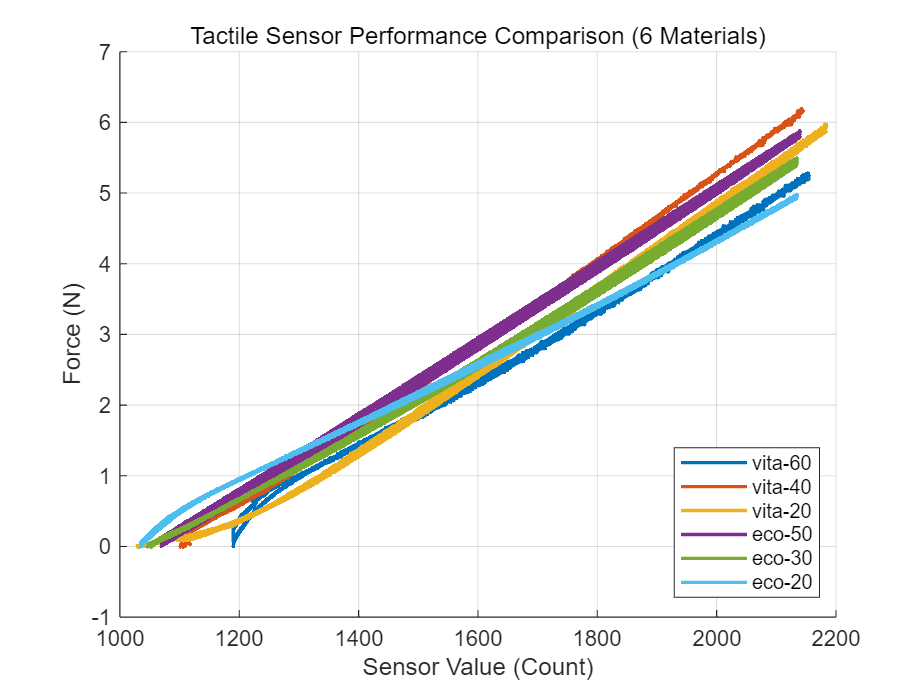


% 7. 그래프 마무리 설정
hold off;
xlabel('Sensor Value (Count)');
ylabel('Force (N)');
title('Tactile Sensor Performance Comparison (6 Materials)');
grid on;
legend('Location', 'best'); 


% ---------------------------------------------------------
% 8. ★★★ 최종 분석 테이블 생성 및 출력 ★★★
% ---------------------------------------------------------

% Material 이름 열 벡터로 변환
Materials = Legend_list'; 

% 테이블 생성
ResultTable = table(Materials, res_range, res_resolution, res_sensitivity, res_rmse, res_rsq, ...
    'VariableNames', {'Material', 'Force_Range_N', 'Resolution_N_per_Count', 'Sensitivity_Count_per_N', 'Linearity_RMSE_N', 'R_Squared'});

disp(' ');

disp('========================================================================================');

disp('                              센서 재료별 성능 분석 결과표                               ');

                              센서 재료별 성능 분석 결과표                               


disp('========================================================================================');

disp(ResultTable);

    Material     Force_Range_N    Resolution_N_per_Count    Sensitivity_Count_per_N    Linearity_RMSE_N    R_Squared
    _________    _____________    ______________________    _______________________    ________________    _________

    "vita-60"       5.2892              0.0050822                   196.77                  0.11008          0.9942 
    "vita-40"       6.2135              0.0057376                   174.29                  0.06363         0.99863 
    "vita-20"       5.9882              0.0051257                   195.09                   0.2083          0.9844 
    "eco-50"        5.8862              0.0053738                   186.09                  0.05597         0.99895 
    "eco-30"        5.5129              0.0049121                   203.58                 0.070614         0.99814 
    "eco-20"        4.9899              0.0043224                   231.35                 0.060694         0.99827 



disp('========================================================================================');


% (선택사항) 엑셀로 저장하고 싶으면 아래 주석 해제
% writetable(ResultTable, 'Sensor_Analysis_Result.xlsx');